对于type 2或以上的系统，一定会产生overshoot


$$P\left(s\right)=\frac{2s+10}{s^2 \left(s+1\right)}$$


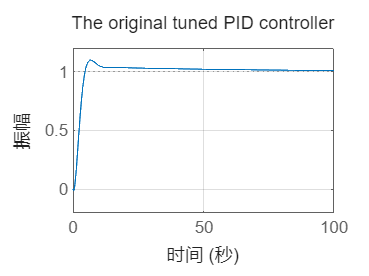

clf; clear;
P = tf([2 -10],[1,1,0,0]);
param = pidtune(P,"PIDF");

% Param
newParam = param;
newParam.Kd = newParam.Kd * 10;

% Two system
sys_original = feedback(series(tf(param), P), 1);
sys_new = feedback(series(tf(newParam), P), 1);

% Plot them
figure;
step(sys_original);
title("The original tuned PID controller");
grid on;

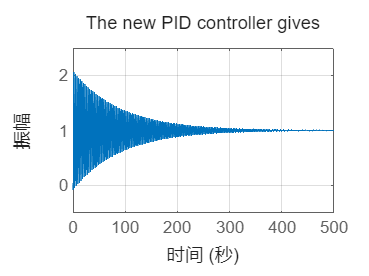


figure;
step(sys_new);
title("The new PID controller gives");
grid on;